omega = 15;
zeta = 1; % A1=1, A2=0
T_L = 0

T_L = 0

J1=0.0198; % kgm^2
J2=0.0242; % kgm^2
J3=0.0027; % kgm^2
J4=0.00038; % kgm^2
qr_1 = 0.34; % rad/s
qr_2 = 0.34; % rad/s
qr_3 = 0.34; % m
qr_4 = 0.34; % rad/s
k_T = 0.17 % Nm/V

k_T = 0.1700

f = 0.000024 % Nm/(rad/s)

f = 2.4000e-05


Kp_1 = (omega^2*J1)/k_T

Kp_1 = 26.2059

Kp_2 = (omega^2*J2)/k_T

Kp_2 = 32.0294

Kp_3 = (omega^2*J3)/k_T

Kp_3 = 3.5735

Kp_4 = (omega^2*J4)/k_T

Kp_4 = 0.5029


Kd_1 = ((2*zeta*Kp_1)/omega)-(f/k_T)

Kd_1 = 3.4940

Kd_2 = ((2*zeta*Kp_2)/omega)-(f/k_T)

Kd_2 = 4.2704

Kd_3 = ((2*zeta*Kp_3)/omega)-(f/k_T)

Kd_3 = 0.4763

Kd_4 = ((2*zeta*Kp_4)/omega)-(f/k_T)

Kd_4 = 0.0669

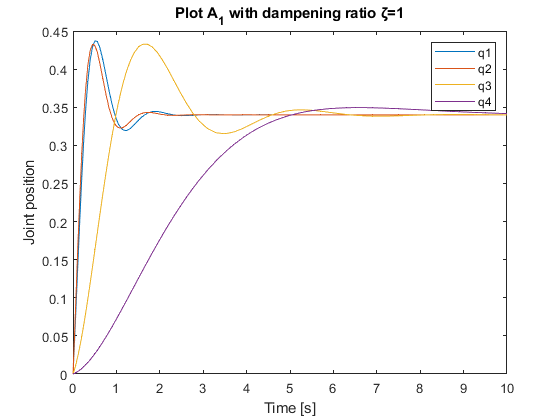


simulink = sim('problem12',10);   % start simulation
%open_system('problem12/Scope')   % open scope
q1 = simulink.get('q1');
q2 = simulink.get('q2');
q3 = simulink.get('q3');
q4 = simulink.get('q4');
plot(q1.Time,q1.Data), hold on
plot(q2.Time,q2.Data)
plot(q3.Time,q3.Data)
plot(q4.Time,q4.Data)
legend('q1','q2','q3','q4')
xlabel('Time [s]') 
ylabel('Joint position')
title('Plot A_1 with dampening ratio ζ=1')